syms s


A = [-1 -1;6 0];
B = [1 1; 1 0];
C = [1 0; 0 1];
D = [0 0; 0 0];
sys = ss(A, B, C, D)

sys =
 
  A = 
       x1  x2
   x1  -1  -1
   x2   6   0
 
  B = 
       u1  u2
   x1   1   1
   x2   1   0
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



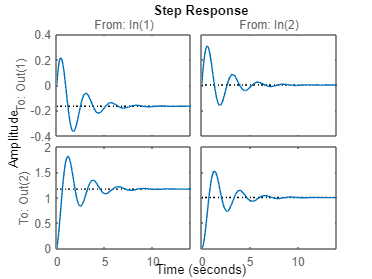


step(sys)

G = C*inv(s*eye(2)- A)*B + D

$$G = \left(\begin{array}{cc} \frac{s}{s^{2}+s+6}-\frac{1}{s^{2}+s+6} & \frac{s}{s^{2}+s+6}\\ \frac{6}{s^{2}+s+6}+\frac{s+1}{s^{2}+s+6} & \frac{6}{s^{2}+s+6} \end{array}\right)$$

eig(A)

ans =   -0.5000 + 2.3979i
  -0.5000 - 2.3979i
